# Impulse Response with Late Reverberations

close all; clear; clc;
list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end
clear list_factory index_interpreter default_name i;

% Add paths
addpath(genpath('Data'));

% Settings
SETTINGS.titleFS    = 18;
SETTINGS.subtitleFS = 15;
SETTINGS.labelFS    = 12;
fs = 44100;

## Excitation Signal (Impulse)

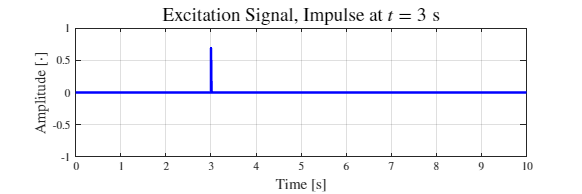

duration_s = 10;
ExcitationSignal = zeros(duration_s*fs, 1);

impulse_amp         = 0.7;
impulse_happening_s = 3;

ExcitationSignal(impulse_happening_s*fs) = impulse_amp;
audiowrite('Data\Impulse.wav', ExcitationSignal, fs);

f = figure('Position', [10 10 900 300]);
t     = (0:1/fs:(length(ExcitationSignal)-1)/fs)';
p = plot(t, ExcitationSignal);
p.Color = [0 0 1];
p.LineWidth = 2;
grid on;
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
title('Excitation Signal, Impulse at $t=3\; \mathrm{s}$', 'FontSize', SETTINGS.subtitleFS);
xticks(0:1:duration_s);
ylim([-1 1]);

% exportgraphics(f, 'Figures\ExcitationSignal_Impulse.pdf', 'Resolution', 200);

## Read Data

%-------------- TEST 1 -------------------------%
test1.dataRaw = readmatrix('Test1.txt');
test1.dataL = test1.dataRaw(1:2:end);
test1.dataR = test1.dataRaw(2:2:end);
test1.t     = (0:1/fs:(length(test1.dataL)-1)/fs)';

test1.signalL = [test1.t test1.dataL];
test1.signalR = [test1.t test1.dataR];
[test1.maxL, test1.IL] = max(test1.dataL);
[test1.maxR, test1.IR] = max(test1.dataR);
test1.signalL(any(abs(test1.signalL) < test1.maxL/1000,2),:) = [];
test1.signalR(any(abs(test1.signalR) < test1.maxR/1000,2),:) = [];

%-------------- TEST 2 -------------------------%
test2.dataRaw = readmatrix('Test2.txt');
test2.dataL = test2.dataRaw(1:2:end);
test2.dataR = test2.dataRaw(2:2:end);
test2.t     = (0:1/fs:(length(test2.dataL)-1)/fs)';

test2.signalL = [test2.t test2.dataL];
test2.signalR = [test2.t test2.dataR];
[test2.maxL, test2.IL] = max(test2.dataL);
[test2.maxR, test2.IR] = max(test2.dataR);
test2.signalL(any(abs(test2.signalL) < test2.maxL/1000,2),:) = [];
test2.signalR(any(abs(test2.signalR) < test2.maxR/1000,2),:) = [];

%-------------- TEST 3 -------------------------%
test3.dataRaw = readmatrix('Test3.txt');
test3.dataL = test3.dataRaw(1:2:end);
test3.dataR = test3.dataRaw(2:2:end);
test3.t     = (0:1/fs:(length(test3.dataL)-1)/fs)';

test3.signalL = [test3.t test3.dataL];
test3.signalR = [test3.t test3.dataR];
[test3.maxL, test3.IL] = max(test3.dataL);
[test3.maxR, test3.IR] = max(test3.dataR);
test3.signalL(any(abs(test3.signalL) < test3.maxL/1000,2),:) = [];
test3.signalR(any(abs(test3.signalR) < test3.maxR/1000,2),:) = [];

%-------------- TEST 4 -------------------------%
test4.dataRaw = readmatrix('Test4.txt');
test4.dataL = test4.dataRaw(1:2:end);
test4.dataR = test4.dataRaw(2:2:end);
test4.t     = (0:1/fs:(length(test4.dataL)-1)/fs)';

test4.signalL = [test4.t test4.dataL];
test4.signalR = [test4.t test4.dataR];
[test4.maxL, test4.IL] = max(test4.dataL);
[test4.maxR, test4.IR] = max(test4.dataR);
test4.signalL(any(abs(test4.signalL) < test4.maxL/1000,2),:) = [];
test4.signalR(any(abs(test4.signalR) < test4.maxR/1000,2),:) = [];

%-------------- TEST 5 -------------------------%
test5.dataRaw = readmatrix('Test5.txt');
test5.dataL = test5.dataRaw(1:2:end);
test5.dataR = test5.dataRaw(2:2:end);
test5.t     = (0:1/fs:(length(test5.dataL)-1)/fs)';

test5.signalL = [test5.t test5.dataL];
test5.signalR = [test5.t test5.dataR];
[test5.maxL, test5.IL] = max(test5.dataL);
[test5.maxR, test5.IR] = max(test5.dataR);
test5.signalL(any(abs(test5.signalL) < test5.maxL/1000,2),:) = [];
test5.signalR(any(abs(test5.signalR) < test5.maxR/1000,2),:) = [];

## Raw Plots

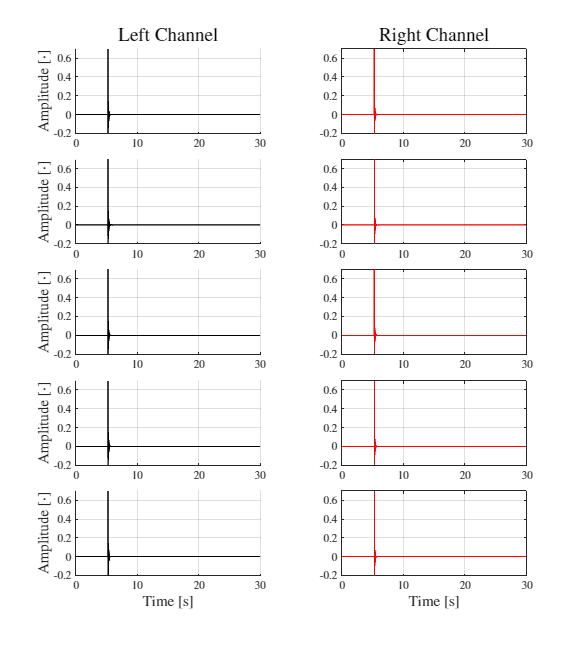

f = figure('Position', [10 10 900 1000]);
tiledlayout(5, 2);

nexttile;
hold on
    p = plot(test1.t, test1.dataL);
    p.Color = [0 0 0];
hold off
grid on
% xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
title('Left Channel', 'FontSize', SETTINGS.subtitleFS)

nexttile;
p = plot(test1.t, test1.dataR);
p.Color = [1 0 0];
grid on
title('Right Channel', 'FontSize', SETTINGS.subtitleFS)

nexttile;
hold on
    p = plot(test2.t, test2.dataL);
    p.Color = [0 0 0];
    
hold off
grid on
% xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(test2.t, test2.dataR);
    p.Color = [1 0 0];
grid on

nexttile;
hold on
    p = plot(test3.t, test3.dataL);
    p.Color = [0 0 0];
hold off
grid on
% xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
    p = plot(test3.t, test3.dataR);
    p.Color = [1 0 0];
grid on

nexttile;
hold on
    p = plot(test4.t, test4.dataL);
    p.Color = [0 0 0];
hold off
grid on
% xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(test4.t, test4.dataR);
p.Color = [1 0 0];
grid on

nexttile;
hold on
    p = plot(test5.t, test5.dataL);
    p.Color = [0 0 0];
hold off
grid on
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

nexttile;
p = plot(test5.t, test5.dataR);
p.Color = [1 0 0];
grid on
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);


% exportgraphics(f, 'Figures\RawPlots.pdf', 'Resolution', 200);

## Designed filter

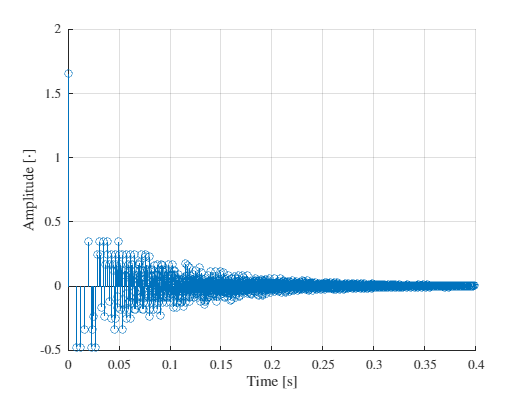

load('Allpass_IR.mat');

[Allpass.maxL, Allpass.IL] = max(signal_all(:, 2));
y_all = signal_all;
signal_all(any(abs(signal_all(:, 2)) < Allpass.maxL/1000,2),:) = [];

figure();
hold on
    stem(signal_all(:, 1), signal_all(:, 2))
hold off
grid on
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);

## Comparison

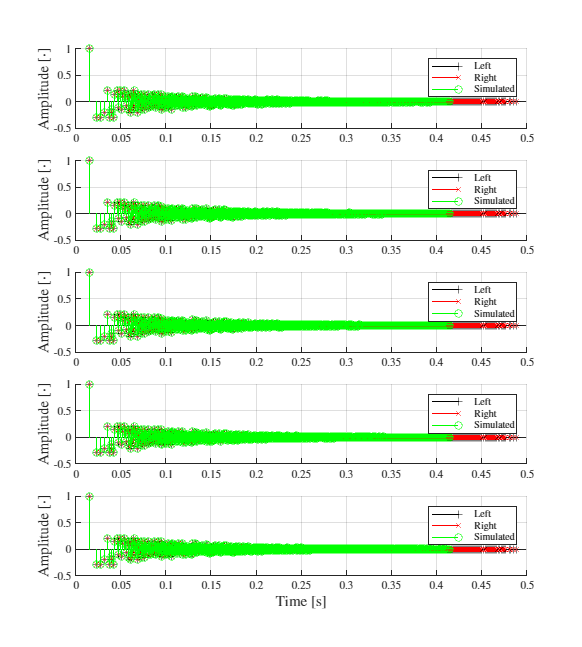

% Align in time
test1.signalL(:, 1)      = test1.signalL(:, 1) - test1.t(test1.IL) + (7.79-1.28*2)/343;
test1.signalR(:, 1)      = test1.signalR(:, 1) - test1.t(test1.IR) + (7.79-1.28*2)/343;
test2.signalL(:, 1)      = test2.signalL(:, 1) - test2.t(test2.IL) + (7.79-1.28*2)/343;
test2.signalR(:, 1)      = test2.signalR(:, 1) - test2.t(test2.IR) + (7.79-1.28*2)/343;
test3.signalL(:, 1)      = test3.signalL(:, 1) - test3.t(test3.IL) + (7.79-1.28*2)/343;
test3.signalR(:, 1)      = test3.signalR(:, 1) - test3.t(test3.IR) + (7.79-1.28*2)/343;
test4.signalL(:, 1)      = test4.signalL(:, 1) - test4.t(test4.IL) + (7.79-1.28*2)/343;
test4.signalR(:, 1)      = test4.signalR(:, 1) - test4.t(test4.IR) + (7.79-1.28*2)/343;
test5.signalL(:, 1)      = test5.signalL(:, 1) - test5.t(test5.IL) + (7.79-1.28*2)/343;
test5.signalR(:, 1)      = test5.signalR(:, 1) - test5.t(test5.IR) + (7.79-1.28*2)/343;
signal_all(:, 1)         = signal_all(:, 1) + (7.79-1.28*2)/343;

% Align in amplitude (normalize)
test1.signalL(:, 2) = test1.signalL(:, 2) ./max(test1.signalL(:, 2));
test1.signalR(:, 2) = test1.signalR(:, 2) ./max(test1.signalR(:, 2)); 
test2.signalL(:, 2) = test2.signalL(:, 2) ./max(test2.signalL(:, 2));
test2.signalR(:, 2) = test2.signalR(:, 2) ./max(test2.signalR(:, 2)); 
test3.signalL(:, 2) = test3.signalL(:, 2) ./max(test3.signalL(:, 2));
test3.signalR(:, 2) = test3.signalR(:, 2) ./max(test3.signalR(:, 2)); 
test4.signalL(:, 2) = test4.signalL(:, 2) ./max(test4.signalL(:, 2));
test4.signalR(:, 2) = test4.signalR(:, 2) ./max(test4.signalR(:, 2)); 
test5.signalL(:, 2) = test5.signalL(:, 2) ./max(test5.signalL(:, 2));
test5.signalR(:, 2) = test5.signalR(:, 2) ./max(test5.signalR(:, 2));  
signal_all(:, 2) = signal_all(:, 2) ./max(signal_all(:, 2));

f = figure('Position', [10 10 900 1000]);
tiledlayout(5, 1);

nexttile;
hold on
    s = stem(test1.signalL(:, 1), test1.signalL(:, 2));
    s.Color = [0 0 0];
    s.Marker = "+";
    s = stem(test1.signalR(:, 1), test1.signalR(:, 2));
    s.Color = [1 0 0];
    s.Marker = "x";
    s = stem(signal_all(:, 1), signal_all(:, 2));
    s.Color = [0 1 0];
    s.Marker = "o";

hold off
grid on
% xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
legend('Left', 'Right', 'Simulated')

nexttile;
hold on
    s = stem(test2.signalL(:, 1), test2.signalL(:, 2));
    s.Color = [0 0 0];
    s.Marker = "+";
    s = stem(test2.signalR(:, 1), test2.signalR(:, 2));
    s.Color = [1 0 0];
    s.Marker = "x";
    s = stem(signal_all(:, 1), signal_all(:, 2));
    s.Color = [0 1 0];
    s.Marker = "o";

hold off
grid on
% xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
legend('Left', 'Right', 'Simulated')

nexttile;
hold on
    s = stem(test3.signalL(:, 1), test3.signalL(:, 2));
    s.Color = [0 0 0];
    s.Marker = "+";
    s = stem(test3.signalR(:, 1), test3.signalR(:, 2));
    s.Color = [1 0 0];
    s.Marker = "x";
    s = stem(signal_all(:, 1), signal_all(:, 2));
    s.Color = [0 1 0];
    s.Marker = "o";

hold off
grid on
% xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
legend('Left', 'Right', 'Simulated')

nexttile;
hold on
    s = stem(test4.signalL(:, 1), test4.signalL(:, 2));
    s.Color = [0 0 0];
    s.Marker = "+";
    s = stem(test4.signalR(:, 1), test4.signalR(:, 2));
    s.Color = [1 0 0];
    s.Marker = "x";
    s = stem(signal_all(:, 1), signal_all(:, 2));
    s.Color = [0 1 0];
    s.Marker = "o";

hold off
grid on
% xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
legend('Left', 'Right', 'Simulated')

nexttile;
hold on
    s = stem(test5.signalL(:, 1), test5.signalL(:, 2));
    s.Color = [0 0 0];
    s.Marker = "+";
    s = stem(test5.signalR(:, 1), test5.signalR(:, 2));
    s.Color = [1 0 0];
    s.Marker = "x";
    s = stem(signal_all(:, 1), signal_all(:, 2));
    s.Color = [0 1 0];
    s.Marker = "o";

hold off
grid on
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
legend('Left', 'Right', 'Simulated')

% exportgraphics(f, 'Figures\IR_Comparison_all.pdf', 'Resolution', 200)

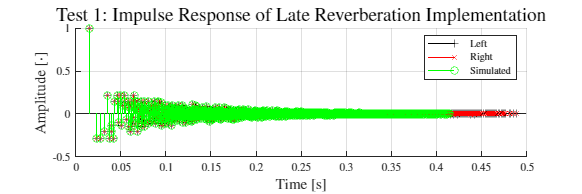

f = figure('Position', [10 10 900 300]);
hold on
    s = stem(test1.signalL(:, 1), test1.signalL(:, 2));
    s.Color = [0 0 0];
    s.Marker = "+";
    s = stem(test1.signalR(:, 1), test1.signalR(:, 2));
    s.Color = [1 0 0];
    s.Marker = "x";
    s = stem(signal_all(:, 1), signal_all(:, 2));
    s.Color = [0 1 0];
    s.Marker = "o";
hold off
grid on
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
legend('Left', 'Right', 'Simulated')
title('Test 1: Impulse Response of Late Reverberation Implementation', 'FontSize', SETTINGS.subtitleFS)
% exportgraphics(f, 'Figures\Test1_IR.pdf', 'Resolution', 200);

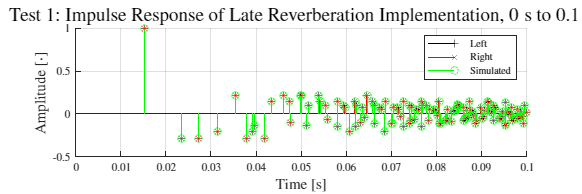


f = figure('Position', [10 10 900 300]);
hold on
    s = stem(test1.signalL(:, 1), test1.signalL(:, 2));
    s.Color = [0 0 0];
    s.Marker = "+";
    s = stem(test1.signalR(:, 1), test1.signalR(:, 2));
    s.Color = [1 0 0];
    s.Marker = "x";
    s = stem(signal_all(:, 1), signal_all(:, 2));
    s.Color = [0 1 0];
    s.Marker = "o";
hold off
grid on
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
legend('Left', 'Right', 'Simulated')
xlim([0 0.1])
title('Test 1: Impulse Response of Late Reverberation Implementation, $0\; \mathrm{s}$ to $0.1\; \mathrm{s}$', 'FontSize', SETTINGS.subtitleFS)
% exportgraphics(f, 'Figures\Test1_IR_ZOOM.pdf', 'Resolution', 200);